# Example 13.2 - Torque-free motion of a spacecraft

A rigid spacecraft with principal moments of inertia $J_{xx}$= 4000 $kg.m^2$, $J_{yy}$ = 7500 $kg.m^2$, $J_{zz}$ = 8500 $kg.m^2$ has an initial angular velocity $\omega(0)$=(0.1, -0.2, 0.5) rad/s and an initial attitude $\psi(0)=0$, $\theta(0)=\frac{\pi}{2}$, $\phi(0)=0$. Simulate the subsequent rotation of the spacecraft

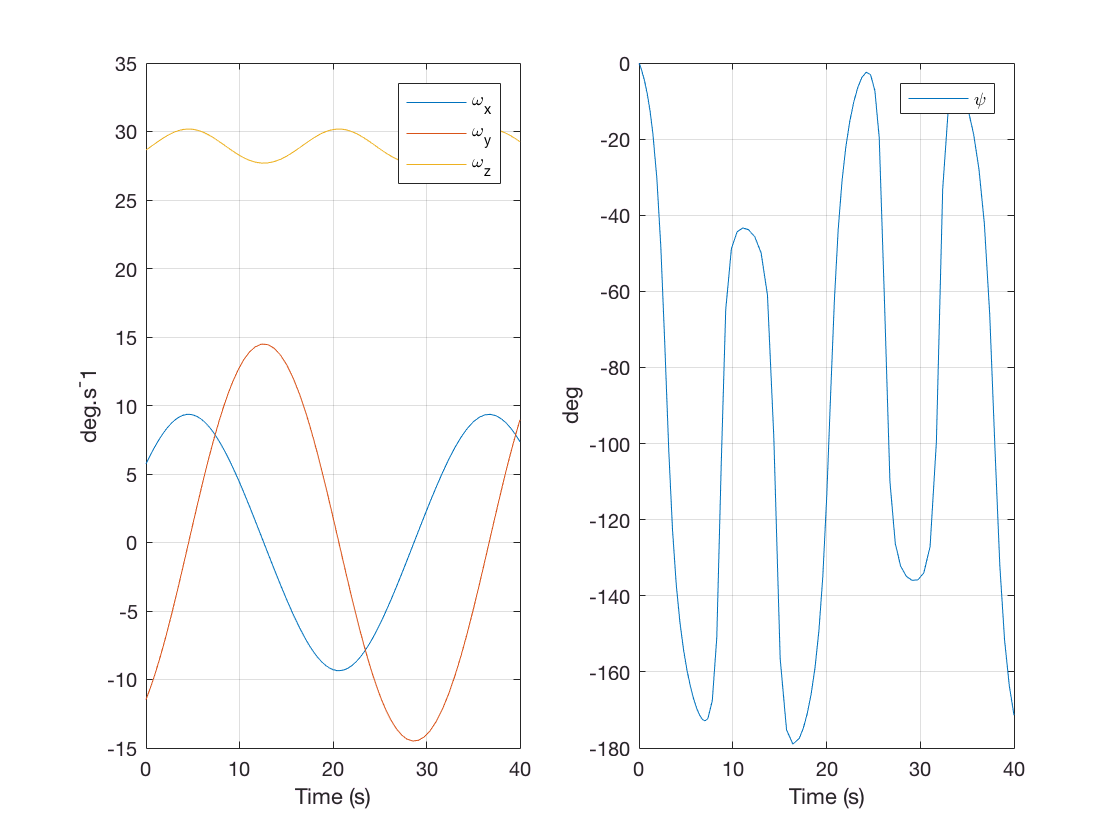


psi0 = 0;theta0 = 0.5*pi;phi0 = 0;
q0 = angle2quat(psi0,theta0,phi0 ,'ZXZ')';
w0 = [0.1 -0.2 0.5]';

[t,x]=ode45(@(t,y) eomRotation(t,y,massModel,forceModel),[0 40],[w0;q0]);
w = x(:,1:3); q = x(:,4:7);
[yaw,pitch,roll] = quat2angle(q,'ZXZ');
subplot(121),plot(t,w*180/pi),grid on;
xlabel('Time (s)');ylabel('deg.s^-1');legend('\omega_x','\omega_y','\omega_z');
subplot(122),plot(t,[yaw pitch roll]*180/pi),grid on;
xlabel('Time (s)');ylabel('deg');legend('\psi','\theta','\psi');

function J = massModel
    J = eye(3);
    J(1,1)=4000; 
    J(2,2)=7500; 
    J(3,3)=8500; 
end

function M = forceModel
    M = zeros(3,1);
end